# Progetto: stabilizzazione di un pendolo inverso su carrello

### Descrizione del problema

Il **sistema** di studio sarà la seguente composizione: pendolo inverso libero di ruotare ancorato ad un carrello libero di traslare.

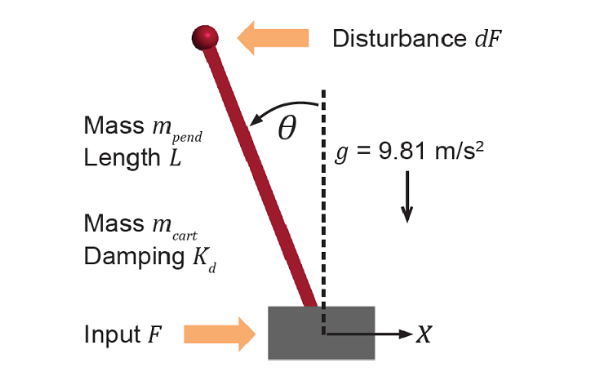

dove i **dati sperimentali **(ideali) del modello sono:

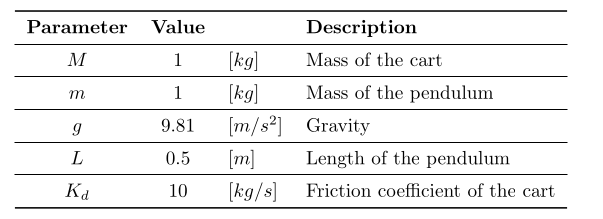

M = 1; m = 1; g = 9.8; L = 0.5; Kd = 10;

Si considerino i seguenti **segnali**

- F = forza in ingresso (controllo)

- x e Teta = spostamento lineare del cart e spostamento angolare del pendolo, misurabili (ingresso da regolare)

- df = forza di disturbo sul pendolo (disturbo)

Il sistema deve lavorare attorno al **punto d'equilibrio **

- Stato d'equilibrio  x = 0  Teta = 0  

- Ingressi d'equilibrio F = 0  dF = 0 

Nota: Intuitivamente è punto d'equilibrio dal punto di vista fisico, ma è possibile verificare che è soluzione imponento tutte le derivate uguali a 0 nelle equazioni differenziali.

### Implementazione del modello fisico su simulink

Le **equazioni dinamiche** del modello trovate sono:

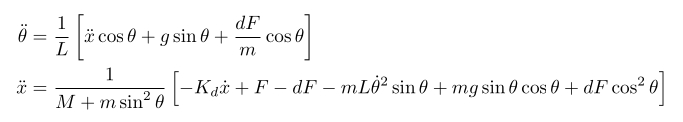

Queste verranno usate per simulare il sistema fisico su simulink: [./sistema_pendolo_carrello.slx](matlab:open('./sistema_pendolo_carrello.slx'))

### **Linearizzazione del sistema attorno all'equilbrio**

Il modello è fortemente non lineare, ma conoscendo le sue equazioni, **possiamo linearizzarlo analiticamente e progettare un controllore nel dominio dei sistemi LTI**.

Scelte le variabili di stato e gli ingressi come:

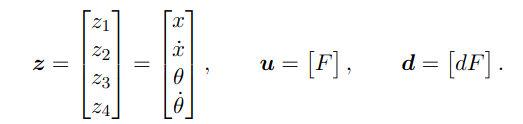

le equazioni di stato sono:

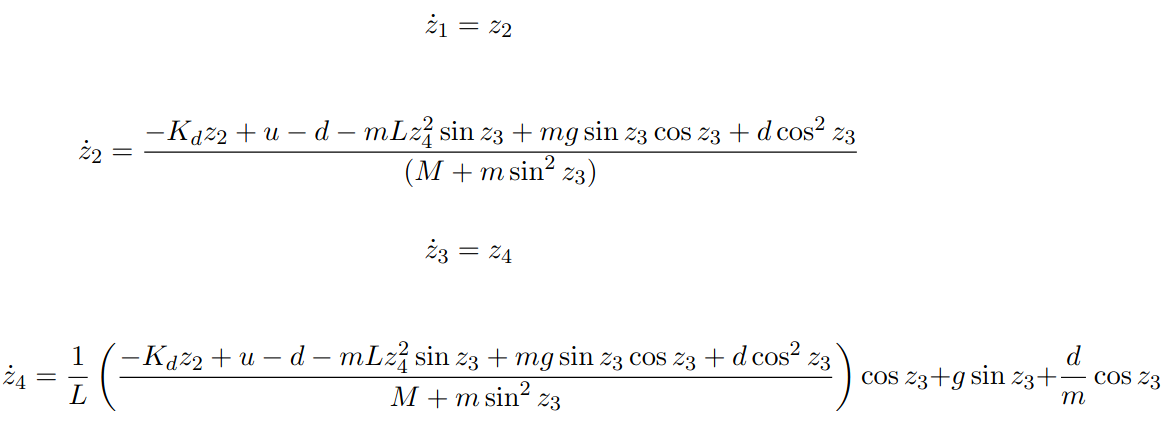

e quelle d'uscita

**Definiamo il sistema **in calcolo simbolico:

% Definizione delle variabili simboliche
syms z1 z2 z3 z4 u d real


% Termine comune complesso (per semplificare la scrittura)
Numerator = -Kd*z2 + u - d - m*L*z4^2*sin(z3) + m*g*sin(z3)*cos(z3) + d*(cos(z3))^2;
Denominator = M + m*(sin(z3))^2;

% Definizione delle equazioni dello stato (dot(z_i))
z1_dot = z2;
z2_dot = Numerator / Denominator;
z3_dot = z4;
z4_dot = (1/L) * ((Numerator / Denominator)*cos(z3) + g*sin(z3) + (d/m) * cos(z3));

%Equazioni d'uscita
y1 = z1;
y2 = z3;

Il sistema linearizzato sarà del tipo:

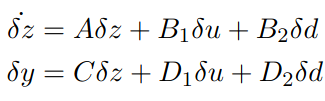

ma siccome stato e ingresso d'equilibrio sono nulli, in realtà coincide con:

**Linearizziamo **calcolando le matrici jacobiane.

% Definizione dei vettori 
Z_dot = [z1_dot; z2_dot; z3_dot; z4_dot];   % Vettore derivata degli stati
Z = [z1; z2; z3; z4];                       % Vettore di Stato
U = [u];                                    % Vettore di Ingresso
D = [d];
Y = [y1; y2];                               % Vettore di Uscita

% Calcolo jacobiani
A_lin_sym = jacobian(Z_dot, Z);     % A = d(Z_dot) / d(Z)
Bu_lin_sym = jacobian(Z_dot, U);    % Bu = d(Z_dot) / d(U)
Bd_lin_sym = jacobian(Z_dot, D);    % Bd = d(Z_dot) / d(D)
C_lin_sym = jacobian(Y, Z);         % C = d(Y) / d(Z)      
Du_lin_sym = jacobian(Y, U);        % Du = d(Y) / d(U) (nota: ovviamente è nullo)
Dd_lin_sym = jacobian(Y, D);        % Du = d(Y) / d(D) (nota: ovviamente è nullo)

**Sostituiamo il punto d'equlibrio **per trovare le matrici del sistema linearizzato

% punto equilibrio
z1_eq = 0; z2_eq = 0; z3_eq = 0; z4_eq = 0;
u_eq = 0; d_eq = 0;

% Vettori dei simboli e dei valori da sostituire
Simboli_da_Sostituire = [z1, z2, z3, z4, u, d];
Valori_Eq = [z1_eq, z2_eq, z3_eq, z4_eq, u_eq, d_eq];

% Matrice linearizzate
A_lin = double(subs(A_lin_sym, Simboli_da_Sostituire, Valori_Eq));
Bu_lin = double(subs(Bu_lin_sym, Simboli_da_Sostituire, Valori_Eq));
Bd_lin = double(subs(Bd_lin_sym, Simboli_da_Sostituire, Valori_Eq));
C_lin = double(subs(C_lin_sym, Simboli_da_Sostituire, Valori_Eq));
Du_lin = double(subs(Du_lin_sym, Simboli_da_Sostituire, Valori_Eq));
Dd_lin = double(subs(Dd_lin_sym, Simboli_da_Sostituire, Valori_Eq));


% Visualizzazione risultati
fprintf('\n*** Matrici del Sistema Linearizzato nel punto z_eq=[0;0;0;0], u_eq=[0;0] ***\n');


*** Matrici del Sistema Linearizzato nel punto z_eq=[0;0;0;0], u_eq=[0;0] ***



fprintf('\nMatrice A:\n'); disp(A_lin)


Matrice A:
         0    1.0000         0         0
         0  -10.0000    9.8000         0
         0         0         0    1.0000
         0  -20.0000   39.2000         0



fprintf('\nMatrice Bu:\n'); disp(Bu_lin)


Matrice Bu:
     0
     1
     0
     2



fprintf('\nMatrice Bd:\n'); disp(Bd_lin)


Matrice Bd:
     0
     0
     0
     2



fprintf('\nMatrice C:\n'); disp(C_lin)


Matrice C:
     1     0     0     0
     0     0     1     0



fprintf('\nMatrice Du:\n'); disp(Du_lin)


Matrice Du:
     0
     0



fprintf('\nMatrice Dd:\n'); disp(Dd_lin)


Matrice Dd:
     0
     0



Ecco quindi il mio sistema linearizzato intorno al pt d'equilibrio.

%def
Gu_lin = ss(A_lin, Bu_lin, C_lin, Du_lin);  %funzione che lega le uscite ad u
Gd_lin = ss(A_lin, Bd_lin, C_lin, Dd_lin);  %funzione che lega le uscite a d

%poli
eig(Gu_lin)

ans =          0
  -11.9096
   -3.2128
    5.1224


eig(Gd_lin) %ovviamente uguale, dipende da A che è lo stesso

ans =          0
  -11.9096
   -3.2128
    5.1224


**Nota importante**

'd' è un disturbo, quindi usiamo soltanto Gu_lin nella progettazione del controllore.

### Stabilizzazione intorno all'equilibrio

Adesso controlliamo il sistema linearizzato.

Siccome parliamo di un sistema MIMO, conviene usare la tecnica **LTR (Loop Transfer Recovery) **per avere immediatamente un controllore "pieno" 2x1.

%estraggo le dimensioni di stato (n), ingresso(k) e uscita(m)
[n_dim, ~] = size(A_lin);
[~, k_dim] = size(Bu_lin);
[m_dim, ~] = size(C_lin);

n_dim, k_dim, m_dim

n_dim = 4

k_dim = 1

m_dim = 2

Matrici dell'**LQR**

%PESI SUGGERITI DA AI
peso_R = 0.01;

Q = [10 0 0 0; 0 10 0 0; 0 0 100 0; 0 0 0 20];   %dim dello stato
R = eye(k_dim) * peso_R;                         %dim dell'ingresso
N_lqr = zeros(n_dim, k_dim);                     %dim di stato-ingresso


% PESI SCELTI CON REGOLA DI BRYSON
% peso_R = 1;
% 
% Q = [1/(10^2) 0 0 0; 0 1/(10^2) 0 0; 0 0 1/(0.26)^2 0; 0 0 0 1/(10)^2];   %dim dello stato
% R = 1/(200^2) * peso_R;                         %dim dell'ingresso
% N_lqr = zeros(n_dim, k_dim);                     %dim di stato-ingresso

Matrici dell'**LTR (LQG)**

Gamma = Bu_lin;

V = eye(m_dim);      %dim dell'uscita

W0 = eye(k_dim);     %dim dell'ingresso perché l'adattamento dimensionale è gestito da gamma*w
Sigma = eye(k_dim);  %stessa dim di w0
p = 1e6;
W = W0 + p*Sigma;

**Sintesi del controllore**

%kc con lqr e %kf con lqe
kc = lqr(A_lin, Bu_lin, Q, R, N_lqr)

kc =   -31.6228  -64.5214  309.7597   77.9455


kf = lqe(A_lin, Gamma, C_lin, W, V, [0 0])

kf = 1.0e+03 *

    0.0155    0.0211
    0.3435    0.6654
    0.0211    0.0477
    0.6700    1.3604



%controllore
kon = tf(ss(A_lin - Bu_lin*kc - kf*C_lin, kf, -kc, 0))


kon =
 
  From input 1 to output:
  -3.612e04 s^3 - 3.861e05 s^2 + 2.151e06 s + 6.198e05
  ----------------------------------------------------
   s^4 + 164.6 s^3 + 8950 s^2 + 4.214e04 s + 7.071e04
 
  From input 2 to output:
  -7.72e04 s^3 - 1.113e06 s^2 - 8.433e06 s - 2.213e07
  ---------------------------------------------------
  s^4 + 164.6 s^3 + 8950 s^2 + 4.214e04 s + 7.071e04
 
Continuous-time transfer function.



eig(kon) %controllo che sia stabile (NECESSARIO PER INTERNA STABILITÀ)

ans =  -79.7755 +42.1755i
 -79.7755 -42.1755i
  -2.5027 + 1.5557i
  -2.5027 - 1.5557i


Controllo la stabilità del sistema a ciclo chiuso calcolando i suoi autovalori (per verificare di aver stabilizzato il sistema).

L_chiuso = minreal(feedback(Gu_lin * kon, [1 0; 0 1], 1)); %**
eig(L_chiuso)

ans =  -95.7552 + 0.0000i
 -34.0753 +32.8001i
 -34.0753 -32.8001i
  -2.5181 + 1.5560i
  -2.5181 - 1.5560i
  -2.3081 + 1.0757i
  -2.3081 - 1.0757i
  -0.9982 + 0.0000i


**NOTA IMPORTANTE**

LTR include direttamente nella definizione del controllore il segno '-' in retroazione, quindi devo usare una **retroazione positiva **

Ciò che possiamo adesso controllare sono i due ingressi X_rif, Teta_rif, in ingresso al sistema a ciclo chiuso

- x vogliamo controllarlo e quindi faremo un ulteriore controllore che poi controlla il sistema stabilizzato.

- Teta invece lo vogliamo sempre nullo, quindi sia per semplificare il sistema, sia per logica, imponiamo qui riferimento sempre a 0 e **riduciamo di un ingresso il nostro sistema**

NOTA: Tutto questo nel simulink verrà implementato con opportuni blocchi, utilizzando il sistema non lineare implementato. (vedi [./sistema_stabilizzato.slx](matlab:open('./sistema_stabilizzato.slx')))

### Prove di stabilità

Possiamo verificare che il controllore abbia stabilizzato il circuito attorno all'equilibrio, se ad esempio facciamo partire il pendolo da posizione instabile.

### Conclusioni:

Il sistema è stato linearizzato attorno al pt d'equilibrio e stabilizzato con un controllore LQR+LQG.